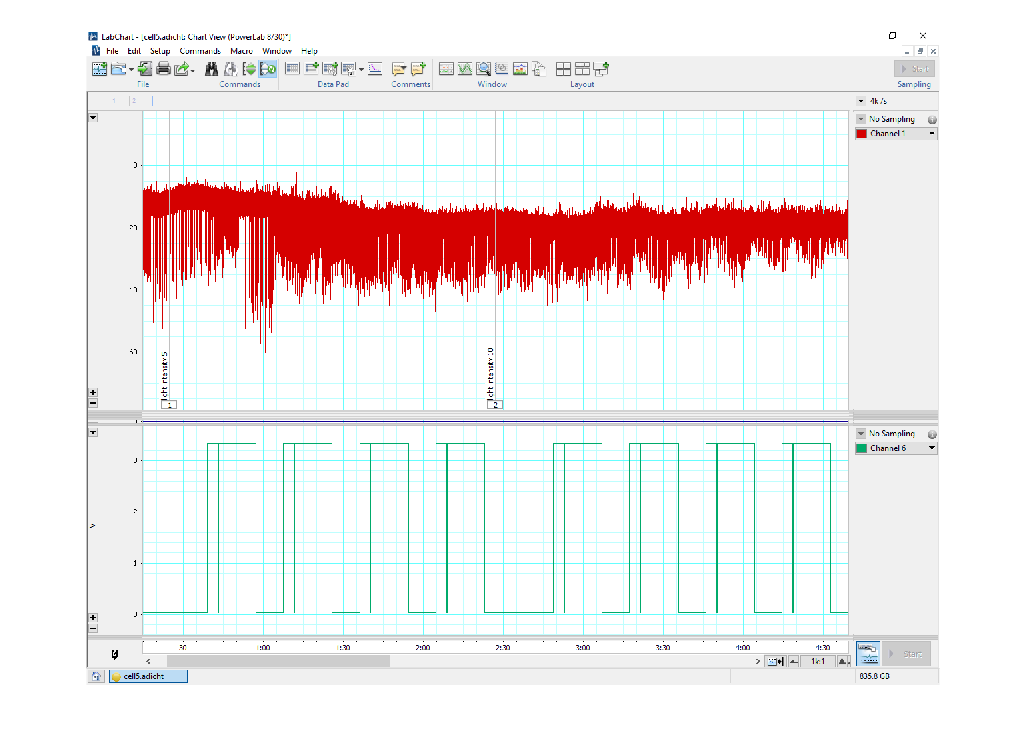

% what labchart file looks like
img = imread('LabChartView.PNG');
figure, imshow(img)

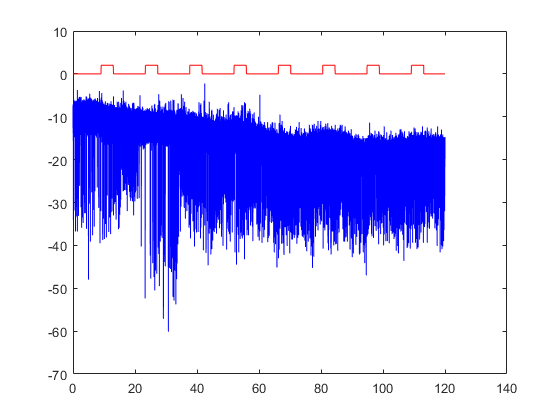

% step 1, export labchart file into .mat with channels and blocks
% interested
% step 2, reads labchart file with interval of interest, generates a TS
% object containing response and stimulus data
t = readLabChart('17033005.mat','interval',[30,150]);

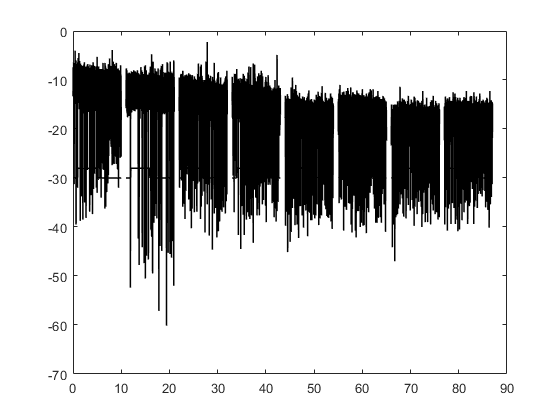


% step 3, segment individual traces
t.segtrace(1,10);

% step 4, show individual traces, we can show all segmented traces or some
% traces by specifying the stimulus number
figure, t.plt('method','fixedlength');

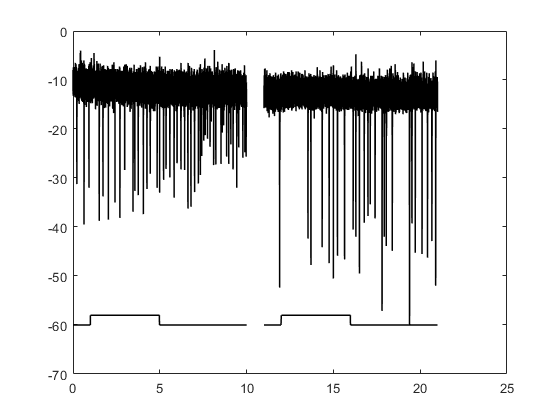

figure, t.plt('method','fixedlength','sti',[1,2]);

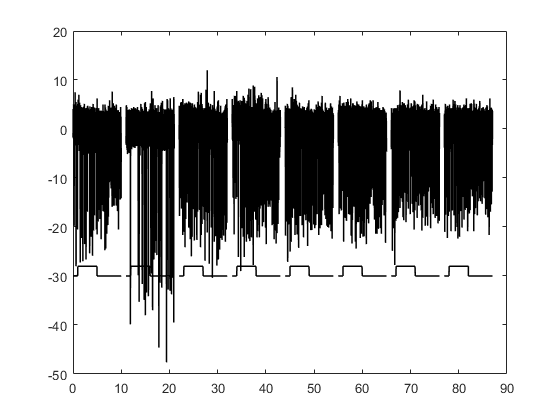

% step 5, adjust baseline using mode 
for i = 1: length(t.stim.startpoint)
    t.seg.d(:,i) = adjustbaseline(t.seg.d(:,i),'option','whole');
end
figure,t.plt('method','fixedlength');

% step 6, detect spikes, threshold -5, polarity, negative, and detect
% spikes from segmented trace (option=1)
t.detectSpike(-5,'negative',1); 

% show results
t.seg.baselinespikerate

ans =      3     3     7     5     4     6     4     6


t.seg.respspikerate

ans =     4.0000    2.0000    4.7500    4.2500    4.2500    5.0000    5.5000    5.0000


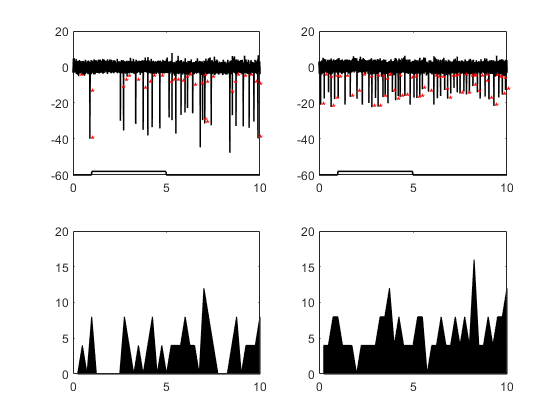

% plot, bin width, 1000, trace#, 2,8, axis, for spikes, [0,10,-60,20] for
% psth, [0,10,0,20]
figure;pltpsth(t,1000,[2,8],[0,10,-60,20;0,10,0,20]);